Brief summary of this function.

Detailed explanation of this function.

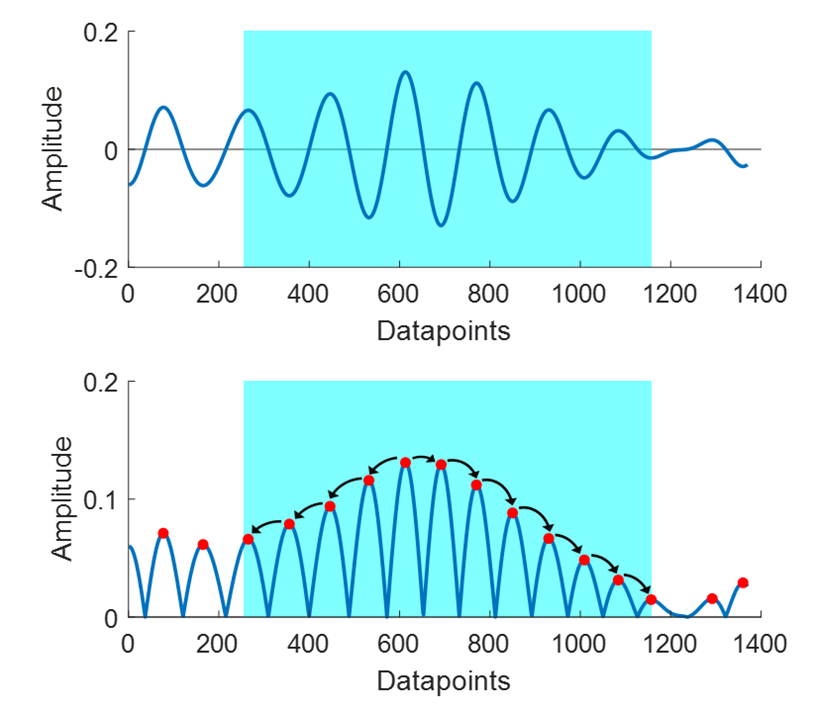

function SS_peaks = Downhill_secondary(app,peaks_value,peaks_index, peak_peaks_index,peak_peaks_value_filtered)

% Preallocate
SS_peaks = zeros(size(peaks_value));
        
% For loops through the highest peaks
counter = 0;
for ii = 1:length(peak_peaks_value_filtered)
    if peak_peaks_value_filtered(ii)>0.5
        SS_peaks(peak_peaks_index(ii))=1;
        for iii = 1:30 %change number based on longest possible spindle duration
            if peaks_index(peak_peaks_index(ii)*2)+iii*10/2>length(app.binary_SS)%  || peak_peaks_index(ii)+iii<=length(peaks_value) %out of bounds to the right %assuming 10 Hz
                break
            else
                if peak_peaks_index(ii) == iii %out of bounds to the left
                    break
                else
                    % right < point && left < point
                    if peak_peaks_index(ii)+iii<= length(peaks_value) && (peak_peaks_index(ii)-iii)>0
                        if peaks_value(peak_peaks_index(ii)+iii)<peaks_value(peak_peaks_index(ii)+(iii-1)) && peaks_value(peak_peaks_index(ii)-iii)<peaks_value(peak_peaks_index(ii)-(iii-1))
                            SS_peaks(peak_peaks_index(ii)+iii)=1;
                            SS_peaks(peak_peaks_index(ii)-iii)=1;
                        else
                            counter = counter+1;
                            SS_peaks(peak_peaks_index(ii)+iii)=0;
                            SS_peaks(peak_peaks_index(ii)-iii)=0;
                            if counter > 1
                                SS_peaks(peak_peaks_index(ii)+iii)=0;
                                SS_peaks(peak_peaks_index(ii)-iii)=0;
                                break
                            end
                        end
                    end
                end
            end
        end
    end
end
end